# 案例：随机行走法求函数的极小值

clear;clc;
lb = [-10, -10];
ub = [10, 10];
x0 = rand(1, 2) .* (ub - lb) + lb;
rng('default');
[mx, minf] = OptRandWalk(x0, 10, 100, 10);
disp(['最优值：' num2str(mx)]);

最优值：3.0168     -0.8653


disp(['最优值对应目标函数：' num2str(minf)]);

最优值对应目标函数：0.0097159


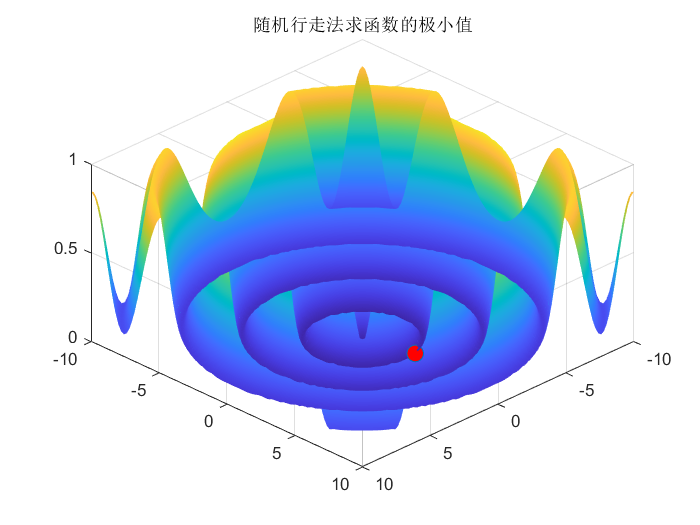

len = 100;
xRange = linspace(-10, 10, len);
yRange = linspace(-10, 10, len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = func([xMap(i, j), yMap(i, j)]);
    end
end
surf(xRange, yRange, zMap);
view(-45, -45);
shading interp
hold on
plot3(mx(1), mx(2), minf, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
title('随机行走法求函数的极小值');

function[mx, minf] = OptRandWalk(x, lamda, N, n)
%{ 
函数功能：随机行走法求函数的极小值
x：初始值；
lamda：步长；
N：为了产生较好点的迭代次数；
n：单步循环行走次数，目的是尽可能走到全局最优点附近
mx：最优解；
minf：最优值。
%}
F = zeros(n, 1);
D = length(x);
X = zeros(n, D);
epsilon = 1e-6;
f1 = func(x);
while lamda  >= epsilon
    k = 1;
    while(k <= N)
        u = 2*rand(n, D) - 1;
        for ii =1 : n
            X(ii, :) = x + lamda*(u(ii, :) / norm(u(ii, :)));
            F(ii) = func(X(ii, :));
        end
        [f11, kk] = min(F);
        if f11 < f1
            f1 = f11;
            x = X(kk, :);
            k = 1;
        else
            k = k + 1;
        end
    end
lamda = lamda / 2;
end
mx = X(kk, :);
minf = f1;
end


function f = func(x)
% f = -sin(sqrt((x(1) - 100).^2 + (x(2) - 100).^2 ) + exp(1)) ./ (sqrt((x(1) - 100).^2 + (x(2) - 100).^2 ) + exp(1)) - 1;
% f = sum(x.^2);
% f = 3*cos(x(1)*x(2)) + x(1) + x(2)^2;
% f = 4*x(1)^2-2.1*x(1)^4+x(1)^6/3+x(1)*x(2)-4*x(2)^2+4*x(2)^4;
% f = 0.5 + (sin(sqrt(x(1)^2 + x(2)^2))^2 - 0.5) / (1 + 0.001*(x(1)^2 + x(2)^2))^2;
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
f = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end